Nbits = 1e6;
in = randi([0, 1], [Nbits, 1])*2-1;

Transmitter

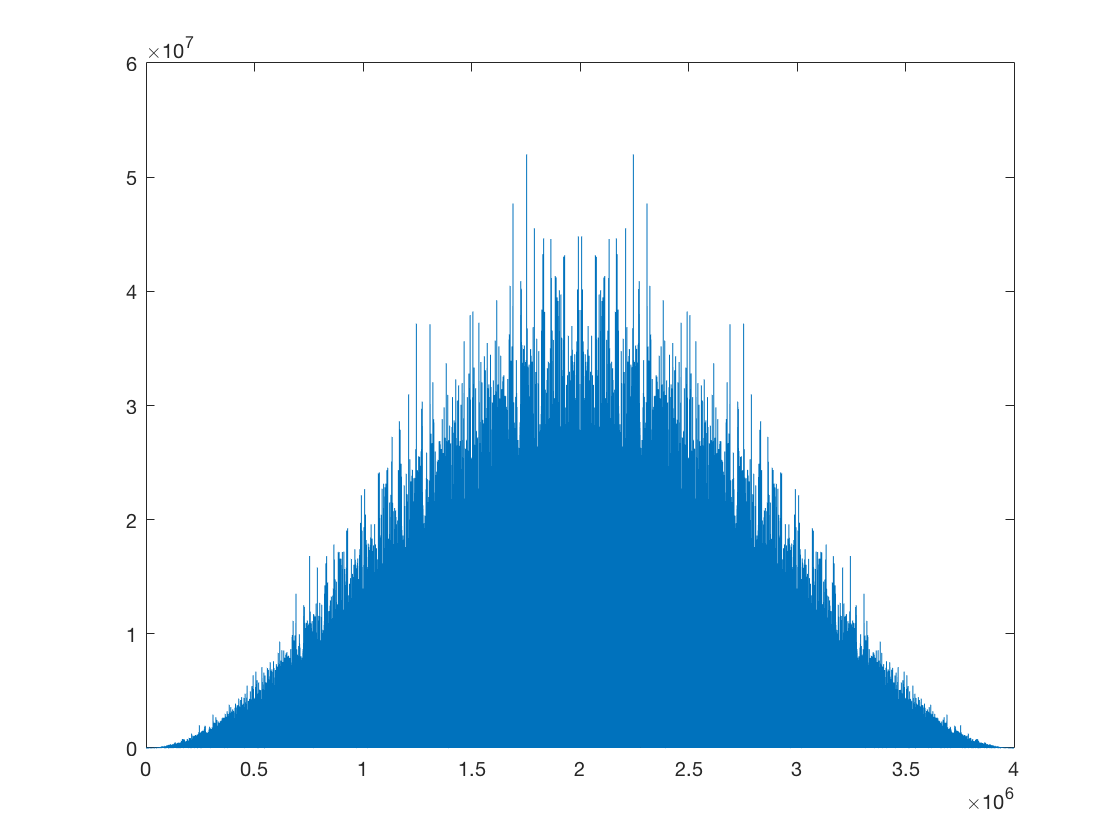

k = 2;
SpS = 2*k;
BpS = 1;
R_s = 1;
R_b = R_s * BpS;
B_sim = SpS * R_s;
v_t = zeros(Nbits*SpS, 1);

% RZ
for a=0:Nbits-1
    for b=1:SpS/2
        v_t(a*SpS+b) = in(a+1);
    end
end
figure(1)
plot(1:Nbits*SpS, fftshift(abs(fft(v_t)).^2))

Calcolo errori a diversi BER

err_arr = zeros(11, 1);
for www=2:12

Rumore Gaussiano Bianco

    EbN0 = (10^(www/10));
    P = mean(abs(in.^2));
    N0 = P/(EbN0*R_b);
    sigma = sqrt((N0/2)*B_sim);
    noise = sigma*randn(Nbits*SpS, 1);
    in_n = v_t+noise;

Filtro di Ricezione

    s_t = zeros(Nbits*SpS, 1);
    for a=1:2
        s_t(a) = 1;
    end
    S_f = (fft(s_t));
    H_rx = S_f;
    X_f = fft(in_n);
    Y_f = H_rx .* X_f;
    y = ifft(Y_f);

Sampling & Decision

Vediamo su quale bit è meglio campionare

    BERs = zeros(SpS, 1);
    for bit = 1:SpS
        r = y(bit:SpS:end) > 0;
        r = 2*r-1;
        err = in ~= r;
        BERs(bit) = sum(err)/Nbits;
    end
    BERs
    [m, i] = min(BERs);
    i

Scegliamo di campionare sul bit i-esimo (è sempre il secondo)

    r = y(i:SpS:end) > 0;
    r = 2*r-1;

Conteggio errori

    err = in ~= r;
    err_arr(www-1) = sum(err)/Nbits;
end

BERs =     0.2648
    0.1039
    0.2648
    0.5000


i = 2

BERs =     0.2398
    0.0787
    0.2401
    0.5001


i = 2

BERs =     0.2142
    0.0564
    0.2144
    0.5003


i = 2

BERs =     0.1877
    0.0376
    0.1876
    0.4999


i = 2

BERs =     0.1588
    0.0230
    0.1591
    0.5000


i = 2

BERs =     0.1317
    0.0125
    0.1311
    0.4995


i = 2

BERs =     0.1041
    0.0059
    0.1044
    0.4998


i = 2

BERs =     0.0797
    0.0024
    0.0798
    0.5000


i = 2

BERs =     0.0572
    0.0008
    0.0568
    0.5003


i = 2

BERs =     0.0379
    0.0002
    0.0378
    0.5001


i = 2

BERs =     0.0234
    0.0000
    0.0233
    0.4996


i = 2

Plotting

err_arr

err_arr =     0.1039
    0.0787
    0.0564
    0.0376
    0.0230
    0.0125
    0.0059
    0.0024
    0.0008
    0.0002


figure(2)
semilogy(2:12, err_arr, 'ro')
hold on

Andamento teorico

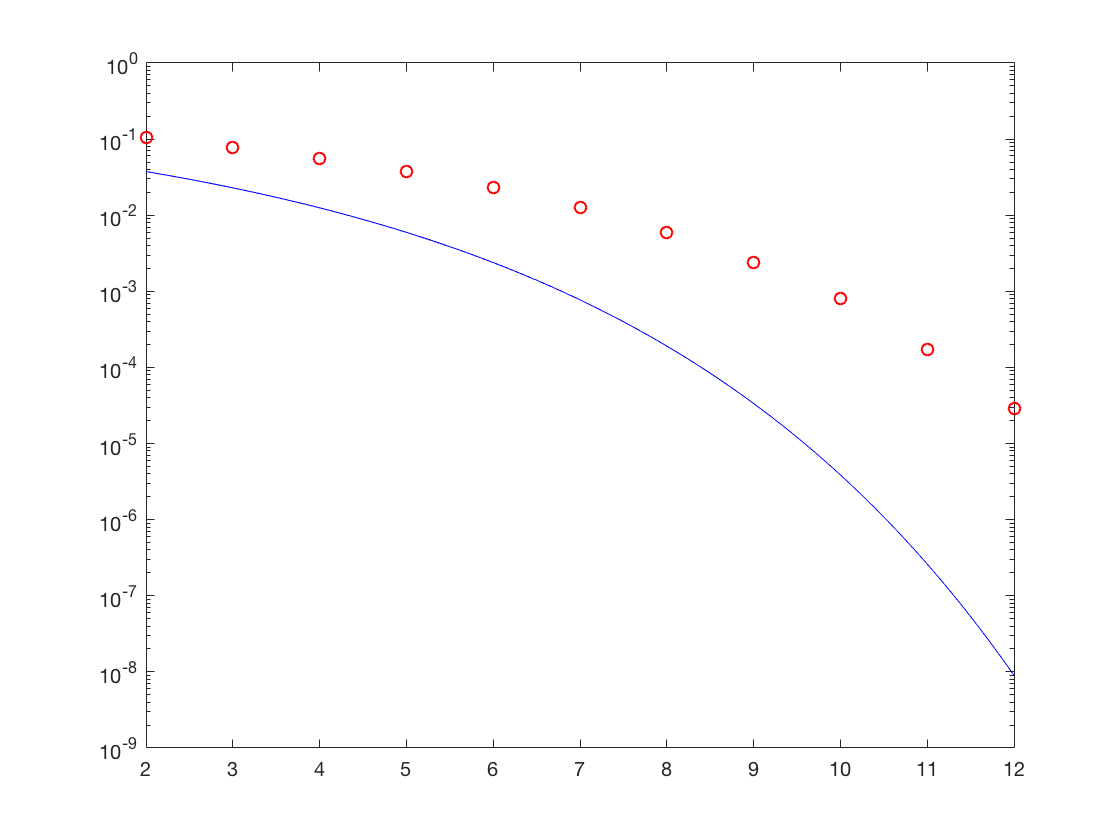

EbN0 = 2:0.1:12;
BER = 0.5*erfc(sqrt(10.^(EbN0/10)));
semilogy(EbN0, BER, 'b-')

Diagramma ad occhio

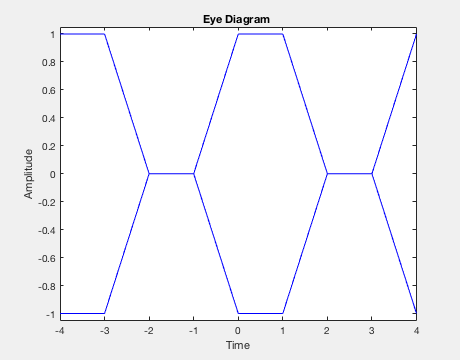

figure(3)
eyediagram(v_t(1:2000*SpS), 2*SpS, 2*SpS);

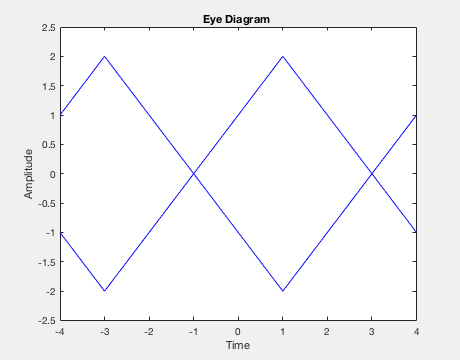



X_f_nn = fft(v_t);
Y_f_nn = H_rx .* X_f_nn;
y_nn = ifft(Y_f_nn);
figure(4)
eyediagram(y_nn(1:2000*SpS), 2*SpS, 2*SpS);